# Signal after MAX2771

%rawdata = randi([0 1], [1 50e3]); 
rawdata = [1 0 1 1 0 1 0 0 0 1];
%rawdata = [1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 ...
% 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1];

%fd      = 50;               % Data frequency
%fca     = 1.023e6;          % C/A code frequency
fd      = 5;               % Data frequency
fca     = 1.023e5;          % C/A code frequency
fc      = fca*20;        % Carrier frequency (Adjusted to not overload RAM)
%fc      = 1575.42e6;        % Carrier frequency
fs      = 10*fc;
sv_id   = 1;                % Satellite Vehicle ID
n       = 1;                % BPSK(1) fc = n*1.023e6; %code rate BPSK(n) 
%                               spreading code rate n*1.023 MHz
codeLength = round(1023/n); 

fdoppler = [10, 30, -20, -50];
ca_codes = [ 1,  8,  20, 12];

%Rsignal = 2*(.25*Received(rawdata,fd,fca,fc,fs,fdoppler(1),ca_codes(1),1,0) + ...
%          .25*Received(rawdata,fd,fca,fc,fs,fdoppler(2),ca_codes(2),1,30) + ...
%          .25*Received(rawdata,fd,fca,fc,fs,fdoppler(3),ca_codes(3),1,834) + ...
%          .25*Received(rawdata,fd,fca,fc,fs,fdoppler(4),ca_codes(4),1,514));

%Rsignal = 2*(.25*Received(rawdata,fd,fca,fc,fs,fdoppler(1),ca_codes(1),1,0) + ...
%            .25*Received(rawdata,fd,fca,fc,fs,fdoppler(4),ca_codes(4),1,514));

Rsignal = 2*(Received(rawdata,fd,fca,fc,fs,fdoppler(1),ca_codes(1),1,10));

[I,Q, clk] = MAX2771(Rsignal, fc, fs, round(5*fs/(20*fca*fd)), false);

clear Rsignal fs;

IQ = I + 1i*Q;

## Defining the PLL tracking loop

function out = cd(IE,QE,IP,QP,IL,QL)      % Code Discriminator
    out = .5*(sqrt(IE.^2 + QE.^2) - sqrt(IL.^2 + QL.^2))/ ...
    (sqrt(IE.^2 + QE.^2) + sqrt(IL.^2 + QL.^2)+1e-100);
%    out = ((IE-IL)*IP + (QE-QL)*QP)/2;
%    out = .5*(sqrt(IE.^2 + QE.^2) - sqrt(IL.^2 + QL.^2))/2;
%    out = ((IE-IL))/sqrt(IP^2+QP^2);
end

IE = 0;
p = 0;
QE = 0;
IP = 0;
QP = 0;
IL = 0;
QL = 0;

nco_out = exp(1i.*2.*pi.*fdoppler(1).*(0:length(IQ)-1)./clk);

gc = data_mapper(gold_code_L1(codeLength,1));
gc = expand(gc,20*length(rawdata));
gc = upsampler(gc,length(IQ)/length(gc));

spacing = length(IQ)/(2*20*length(rawdata)*1023);

gce = circshift(gc, -spacing);
gcl = circshift(gc, spacing);

IQ_data = zeros(1,length(IQ));
filter_in = 0;
filter_out = 0;
filt_I = 0;

block_size = length(IQ)/(20*length(rawdata));

Ki = .01;
Kp = .5;
Kd = .001;

for i = 1:length(IQ)/block_size
    idx = (1:block_size) + (i - 1) * block_size;
    
    correlated_E = IQ(idx) .* gce(idx) .* nco_out(idx);
    correlated_P = IQ(idx) .* gc(idx) .* nco_out(idx);
    correlated_L = IQ(idx) .* gcl(idx) .* nco_out(idx);

    IQ_data(idx) = correlated_P;

    IE(i) = sum(real(correlated_E));
    QE(i) = sum(imag(correlated_E));
    IP(i) = sum(real(correlated_P));
    QP(i) = sum(imag(correlated_P));
    IL(i) = sum(real(correlated_L));
    QL(i) = sum(imag(correlated_L));
    
    % Filtro a ajustar """
    filter_in(i+1) = filter(ones(1,5)/5,1,cd(IE(i),QE(i),IP(i),QP(i),IL(i),QL(i)));
    %filter_in(i+1) = cd(IE(i),QE(i),IP(i),QP(i),IL(i),QL(i));
    filt_I = Ki*filter_in(i+1) + filt_I;
    filt_D = Kd*(filter_in(i+1)-filter_in(i));
    filter_out(i) = -Kp*(filter_in(i+1) + filt_I + filt_D);
    p = p + round(filter_out(i));

    gc = circshift(gc,round(filter_out(i)));
    gce = circshift(gc,-spacing);
    gcl = circshift(gc, spacing);

    % """
end

IQ_data = zeros(1,length(IQ));
filter_in(1) = filter_in(end);
filter_out(1) = filter_out(end);

tic = 100;

IE = 0;
QE = 0;
IP = 0;
QP = 0;
IL = 0;
QL = 0;

for k = 1:tic
    for i = 1:length(IQ)/block_size
        idx = (1:block_size) + (i - 1) * block_size;
        
        correlated_E = IQ(idx) .* gce(idx) .* nco_out(idx);
        correlated_P = IQ(idx) .* gc(idx) .* nco_out(idx);
        correlated_L = IQ(idx) .* gcl(idx) .* nco_out(idx);
    
        IQ_data(idx) = correlated_P;
    
        IE(i) = sum(real(correlated_E));
        QE(i) = sum(imag(correlated_E));
        IP(i) = sum(real(correlated_P));
        QP(i) = sum(imag(correlated_P));
        IL(i) = sum(real(correlated_L));
        QL(i) = sum(imag(correlated_L));
        
        filter_in(i+1) = filter(ones(1,5)/5,1,cd(IE(i),QE(i),IP(i),QP(i),IL(i),QL(i)));
        %filter_in(i+1) = cd(IE(i),QE(i),IP(i),QP(i),IL(i),QL(i));
        filt_I = Ki*filter_in(i+1) + filt_I;
        filt_D = Kd*(filter_in(i+1)-filter_in(i));
        filter_out(i) = -Kp*(filter_in(i+1) + filt_I + filt_D);
        p = p + round(filter_out(i));
    
        gc = circshift(gc,round(filter_out(i)));
        gce = circshift(gc,-spacing);
        gcl = circshift(gc, spacing);
    end
end

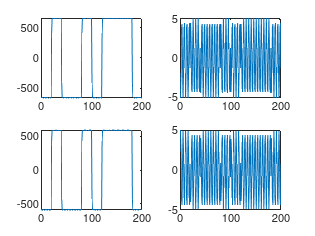

figure Name correlators;
subplot(2,2,1);
plot(IE);
subplot(2,2,2);
plot(QE);
subplot(2,2,3);
plot(IL);
subplot(2,2,4);
plot(QL);

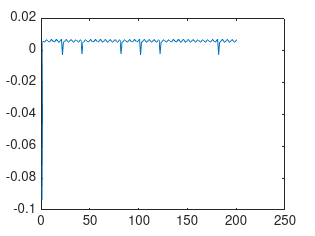

figure;
plot(filter_in);

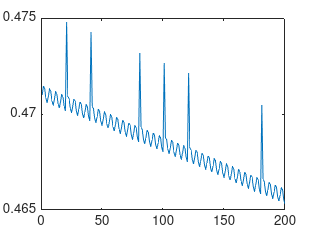

figure Name filter;
plot(filter_out)

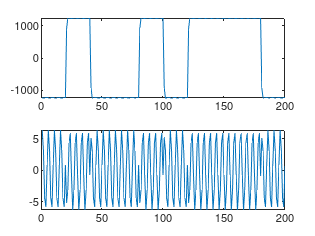

figure Name correlator;
subplot(2,1,1);
plot(IP);
subplot(2,1,2);
plot(QP);

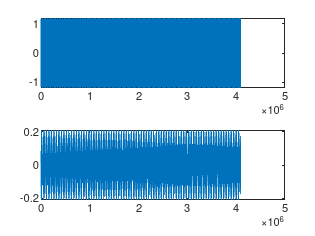

figure Name checking;
subplot(2,1,1);
plot(real((IQ.*gc.*nco_out)));
subplot(2,1,2);
plot(imag((IQ.*gc.*nco_out)));

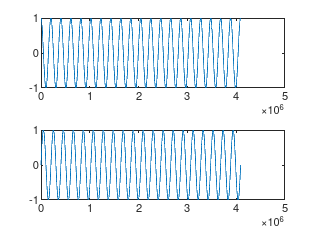

figure Name checking2;
subplot(2,1,1);
plot(real(nco_out));
subplot(2,1,2);
plot(imag(nco_out));

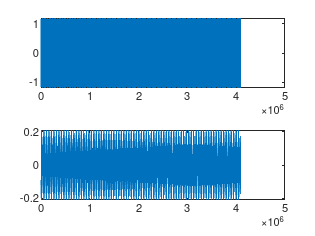

figure Name checking3;
subplot(2,1,1);
plot(real(IQ_data));
subplot(2,1,2);
plot(imag(IQ_data));